# Matrices especiales

Hay un grupo de matrices que destacan por encima de cualquier matriz `nxm`. A continuación se muestra se las detalla y al final se muestra una tabla de resumen con las funciones que las generan.

## Matriz vacía

Se inicia la descripción de matrices especiales con la matriz vacía. En esencia no hay ninguna función que cree una matriz vacía, debido a que es suficiente con abrir y cerrar corchetes `[]` para generarla.

A = []

## Matriz de ceros

Una matriz de ceros se caracateriza, como su nombre lo indica, por una matriz en la que todos sus elementos con `0`. Mediante la función `zeros` es posible generarla.

B1 = zeros(5)       % Si sólo se ingresa un argumento, la matriz generada es cuadrada mxm.


A =

     []




B2 = zeros(3,2)     % Matriz de ceros 3x2.

Un ejemplo podría ser crear un vector fila con el valor de `pi` en todas las entradas.

B3 = zeros(1,5) + pi

B1 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


## Matriz de unos

Esta matriz es similar a la matriz de ceros: en lugar de tener `0` en sus elementos tiene `1`. Con la función `ones` es posible generarla.

C1 = ones(5)       % Si sólo se ingresa un argumento, la matriz generada es cuadrada mxm.

B2 =      0     0
     0     0
     0     0



C2 = ones(3,2)     % Matriz de unos 3x2.

B3 =     3.1416    3.1416    3.1416    3.1416    3.1416


Un ejemplo podría ser crear un vector fila con el valor de `e` en todas las entradas.

C3 = ones(1,5) * exp(1)

C1 =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


**Nota:** A simple vista pareciera no tener utilidad una matriz de ceros o unos, sin embargo, se las puede utilizar como un marcador de posición (**placeholder**) para futuros cálculos, por dar un ejemplo.

- Las matrices de marcadores (**placerholders**) son de gran utilidad en estructuras de bucle (**loop**) que se estudiarán en capítulos posteriores.

## Matriz diagonal

La función `diag` extrae la diagonal principal de una matriz.

D = [

C2 =      1     1
     1     1
     1     1


    1 2 3
    3 4 5

C3 =     2.7183    2.7183    2.7183    2.7183    2.7183


    1 2 3
    ];

diag(D)

Añadiendo un segundo argumento **k** a la función `diag` es posible extraer otras diagonales. La siguiente figura detalla cómo funciona.

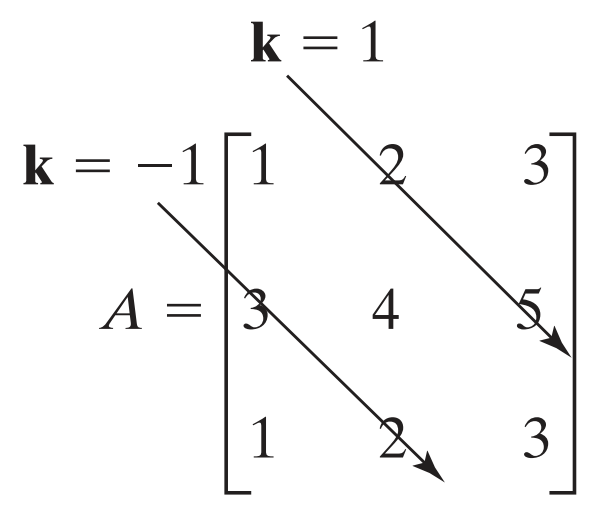

diag(D,1)
diag(D,-1)

Sin embargo, ¿qué pasaría si en lugar de pasarle una matriz como argumento a la función `diag` le pasamos un vector?

E1 = 1:3;

ans =      1
     4
     3


E2 = [3:-1:1]';

diag(E1)

ans =      2
     5


diag(E2)

ans =      3
     2


Como se observa en los resultados, pasarle como argumento un vector fila/columna a la función `diag` generará una matriz en la que la diagonal principal serán los valores del vector y el resto de entradas serán cero.

Por otra parte, ¿qué pasaría si le pasamos un vector y un valor para **k**?

diag(E1,1)
diag(E2,-1)

Como podemos observar, si le pasamos un valor de **k** a la función `diag`, habiéndole pasado un vector como primer argumento, generará una matriz en la que la diagonal donde se ubiquen los valores del vector dependerá del valor de **k**.

## Matriz mágica

MATLAB incluye una función matricial llamada `magic` que genera una matriz con propiedades inusuales.

- La suma de las filas es la misma.

- La suma de las columnas es la misma.

- La suma de las diagonales es la misma.

- La suma de las filas, columnas y diagonales es la misma.

Sin embargo, actualmente parece no existir algún uso práctico para las matrices mágicas, excepto que son divertidas.

F = magic(4)

ans =      1     0     0
     0     2     0
     0     0     3


Revisemos la suma de las columnas:

sum(F)

ans =      3     0     0
     0     2     0
     0     0     1


Revisemos la suma de las filas:

sum(F')

ans =      0     1     0     0
     0     0     2     0
     0     0     0     3
     0     0     0     0


Revisemos la suma de la diagonal principal:

sum(diag(F))

ans =      0     0     0     0
     3     0     0     0
     0     2     0     0
     0     0     1     0


Para revisar la suma de la otra diagonal es necesario "voltear" la matriz. Para ello utilizamos la función `fliplr` (se detalla esta función en la tabla resumen del final).

sum(fliplr(diag(F)))

F =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


ans =     34    34    34    34


ans =     34    34    34    34


ans =          34.00


ans =          34.00


Tal como esperábamos, se cumplen las propiedades de una matriz mágica.

## Tabla resumen de matrices especiales

A continuación se presenta una tabla que detalla algunas funciones para generar matrices especiales.